clear;
clc;
close all;

%% The Main Variables Declared
r=0.15;  % [m] Distance from hinge to actuator connection (DO to EO)
Ro=020;   % [m] Distance from hinge to the actuator fixed point (DO to FO)
Bo_deg=30;  % [degrees] Initial Angle between DOFO and DOEO

Bo=Bo_deg*pi/180;

%% Now to Claculate the Initial Length of the actuator (Lo) using the cosine rule
Lo=sqrt(r^2+Ro^2-2*r*Ro*cos(Bo));
fprintf('Neutral actuator length Lo =%.1f mm\n',Lo*1000);

Neutral actuator length Lo =19870.2 mm


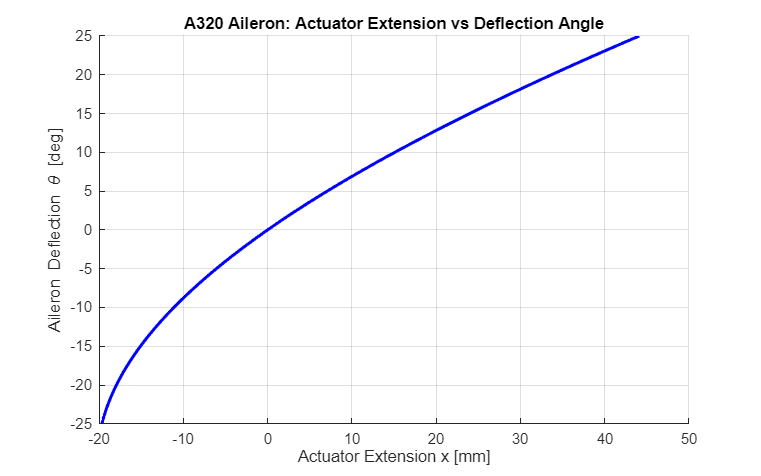


%% Now just to declare the ranges of the aileron deflection
theta_min_deg=-25;
theta_max_deg=25;
theta_deg=linspace(theta_min_deg,theta_max_deg,100);

theta_rad=theta_deg*pi/180;

L=zeros(size(theta_rad));  % Array that will hold the values of L (new Lengths of the actuator) as they are being calculated in the for loop


for i=1:length(theta_rad)
    B =Bo+theta_rad(i);               % New Angle calculated
    L(i)=sqrt(r^2+Ro^2-2*r*Ro*cos(B));     %New Actuator length
end

x=L-Lo;  % The Extension
x_mm=x *1000;

figure('Position',[100 100 800 500]);

hold on;
%Now the plot commences
plot(x_mm,theta_deg,'b-','LineWidth',2);
xlabel('Actuator Extension x [mm]');
ylabel('Aileron Deflection \theta [deg]');
title('A320 Aileron: Actuator Extension vs Deflection Angle');
grid on;
hold off;